The population of a region is growing exponentially. There were 40000000 people in 1980 (when t = 0) and 56000000 in 1990. Build a mathematical model for the population at any time t, in years.

(a) What will be the population in the year 2000?

(b) What is the doubling time?

syms k t
y(t) = 40000000 * exp(k * t)

$$y(t) = 40000000\,{\mathrm{e}}^{k\,t}$$

eqn = y(10) == 56000000

$$eqn = 40000000\,{\mathrm{e}}^{10\,k}=56000000$$

k = double (solve (eqn, k))

k = 0.0336

y(t) = subs (y(t))

$$y(t) = 40000000\,{\mathrm{e}}^{\frac{2424537983148499\,t}{72057594037927936}}$$


% Population in the year 2000 (t = 20)
y_2000 = y(20)

$$y\_2000 = 40000000\,{\mathrm{e}}^{12122689915742495/18014398509481984}$$


% Doubling Time
eqn = [y(t) == 80000000]

$$eqn = 40000000\,{\mathrm{e}}^{\frac{2424537983148499\,t}{72057594037927936}}=80000000$$

t_double = solve(eqn, t)

$$t\_double = \frac{72057594037927936\,\log\left(2\right)}{2424537983148499}$$

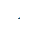


% Graph
hold on
fplot(y(t), [40000000 100000000])
xlabel('Time (in years)')
ylabel ('Population')
hold off